# Actividad 6: Robot angular (2gdl)

**Paola Rojas Domínguez A01737136**

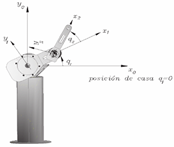

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores. Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t)  t   %Angulos de cada articulación
syms th1p(t) th2p(t)    %Velocidades de cada articulación
syms th1pp(t) th2pp(t)  %Aceleraciones de cada articulación
syms m1 m2 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2   %Masas y matrices de Inercia
syms l1 l2 lc1 lc2 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

Creamos el vector de coordenadas articulares

Q= [th1; th2];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
/ th1(t) \
|        |
\ th2(t) /



Creamos el vector de velocidades articulares. La velocidad articular es la derivada temporal de las coordenadas articulares.

Qp= [th1p; th2p];
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/ th1p(t) \
|         |
\ th2p(t) /



Creamos el vector de aceleraciones articulares. La aceleración articular es la derivada temporal de las velocidades articulares.

Qpp= [th1pp; th2pp];
disp('Aceleraciones generalizadas'); pretty (Qpp);

Aceleraciones generalizadas
/ th1pp(t) \
|          |
\ th2pp(t) /



Se configura el robot con dos articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 0];

Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot. Aquí, 2 GDL corresponden a las dos articulaciones rotacionales.

GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

### Articulación 1 

%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

### Articulación 2

%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty (A(:,:,i));

    %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end

    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1
/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación local A2
/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2
/ #2, -#1, 0, #2 l2 + cos(th1(t)) l1 \
|                                    |
| #1,  #2, 0, #1 l2 + sin(th1(t)) l1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




## Cálculo de las velocidades para cada eslabón

Para calcular la energía cinética más adelante, necesitamos obtener las velocidades lineales y angulares de cada eslabón en función del jacobiano y las velocidades articulares.

### Velocidades para eslabón 2

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
V2=simplify (Jv_a*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2'); pretty(V2);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2
/ - th1p(t) (#1 l2 + sin(th1(t)) l1) - l2 #1 th2p(t) \
|                                                    |
|  th1p(t) (#2 l2 + cos(th1(t)) l1) + l2 #2 th2p(t)  |
|                                                    |
\                          0                         /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




W2=simplify (Jw_a*Qp);
disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2'); pretty(W2);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2
/         0         \
|                   |
|         0         |
|                   |
\ th1p(t) + th2p(t) /



### Velocidades para eslabón 1

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 1
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1'); pretty(V1);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1
/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



W1=simplify (Jw_a1*Qp(1));
disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1'); pretty(W1);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1
/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



## Energía Cinética

La energía cinética de un sistema mecánico se obtiene a partir de la suma de las energías cinéticas de cada eslabón del robot. Esta energía considera tanto el movimiento lineal del centro de masa de cada eslabón como su movimiento rotacional en torno a su eje.

%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];


%Función de energía cinética

%Extraemos las velocidades lineales del efector final en cada eje
V2=V2(t);  
Vx= V2(1,1);
Vy= V2(2,1);
Vz= V2(3,1);

%Extraemos las velocidades angular del efector final en cada ángulo de Euler
W2=W2(t);
W_pitch= W2(1,1);
W_roll= W2(2,1);
W_yaw= W2(3,1);

Con las velocidades obtenidad anteriormente, podemos calcular la energía cinética para cada uno de los eslabones.

### Eslabón 1

V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
K1= simplify (K1);
disp('Energía Cinética en el Eslabón 1'); pretty (K1);

Energía Cinética en el Eslabón 1
              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (lc1 + l1) (l1 |lc1|  + lc1 |l1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1



### Eslabón 2

V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
K2= simplify (K2);
disp('Energía Cinética en el Eslabón 2'); pretty (K2);

Energía Cinética en el Eslabón 2
__                                                                                    _______          __       ______  __    _______         __       ______  ___       __                                                                                    _______          __       ______  __    _______         __       ______  ___          / _______   _______ \
m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)   m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)      | th1p(t)   th2p(t) |
---------------------------------------------------------------------------------------------------------------------------------------------------------------------- + ------------------------------------------------------------------------

### Energía cinética total

Finalmente, la energía cinética total del sistema es la suma de las contribuciones individuales

K_Total= simplify (K1+K2);
disp('Energía Cinética Total'); pretty (K_Total);

Energía Cinética Total
          __                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___              ______           __                     2           2
Izz1 #5   m2 (th1p(t) (sin(#4) l2 + sin(th1(t)) l1) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (cos(#4) l2 + cos(th1(t)) l1) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)   #5 cos(th1(t) - th1(t)) m1 (lc1 + l1) (l1 |lc1|  + lc1 |l1| )
------- + ------------------------------------------------------------------------------------

## Energía Potencial

La energía potencial del sistema se debe a la influencia de la gravedad en los eslabones.

%Obtenemos las alturas respecto a la gravedad
h1= P01(2);
h2= P12(2);

U1=m1*g*h1;
U2=m2*g*h2;

%Calculamos la energía potencial total
U_Total= U1 + U2;
disp('Energía Potencial Total'); pretty(U_Total);

Energía Potencial Total
sin(th2(t)) g lc2 m2 + sin(th1(t)) g lc1 m1



## Modelo de energía

El modelo de energía del robot se describe mediante el Lagrangiano, que es la diferencia entre la energía cinética y la energía potencial

%Obtenemos el Lagrangiano
Lagrangiano= simplify (K_Total - U_Total);
disp('Lagrangiano'); pretty (Lagrangiano);

Lagrangiano
          __                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___                                                            ______           __                     2           2
Izz1 #5   m2 (th1p(t) (sin(#4) l2 + sin(th1(t)) l1) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (cos(#4) l2 + cos(th1(t)) l1) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)                                                 #5 cos(th1(t) - th1(t)) m1 (lc1 + l1) (l1 |lc1|  + lc1 |l1| )
------- + ---

Finalmente, la energía total del sistema es la suma de ambas contribuciones

%Modelo de Energía
H= simplify (K_Total + U_Total);
disp('Modelo de energía'); pretty (H)

Modelo de energía
          __                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___                                                            ______           __                     2           2
Izz1 #5   m2 (th1p(t) (sin(#4) l2 + sin(th1(t)) l1) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (cos(#4) l2 + cos(th1(t)) l1) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)                                                 #5 cos(th1(t) - th1(t)) m1 (lc1 + l1) (l1 |lc1|  + lc1 |l1| )
-------

toc

Elapsed time is 8.969708 seconds.
